# Position visualization 

The goal of this live script is to first visualize the relation between two inputs (phi x and phi z) and the resulting height and radial distance. If a continuous surface is formed a function fit can be applied, and thus a quick way of computing the the positions of points from the motor positions would be created

### Setup

clear all; close all;
addpath("Kinematics")
addpath("Kinematics\Plotting")

For curve fitting the two axisses have to be equal in array size

pos = ArmPos;
n_steps = 200;
x_stepsize = (ArmPos.phiXmax - ArmPos.phiXmin)/n_steps;
z_stepsize = (ArmPos.phiZmax - ArmPos.phiZmin)/n_steps;
[phiX,phiZ] = meshgrid( ...
    ArmPos.phiXmin:x_stepsize:ArmPos.phiXmax, ...
    ArmPos.phiZmin:z_stepsize:ArmPos.phiZmax)

phiX =     0.2000    0.2064    0.2127    0.2191    0.2254    0.2318    0.2381    0.2445    0.2508    0.2572    0.2635    0.2699    0.2762    0.2826    0.2890    0.2953    0.3017    0.3080    0.3144    0.3207    0.3271    0.3334    0.3398    0.3461    0.3525    0.3588    0.3652    0.3716    0.3779    0.3843    0.3906    0.3970    0.4033    0.4097    0.4160    0.4224    0.4287    0.4351    0.4415    0.4478    0.4542    0.4605    0.4669    0.4732    0.4796    0.4859    0.4923    0.4986    0.5050    0.5113
    0.2000    0.2064    0.2127    0.2191    0.2254    0.2318    0.2381    0.2445    0.2508    0.2572    0.2635    0.2699    0.2762    0.2826    0.2890    0.2953    0.3017    0.3080    0.3144    0.3207    0.3271    0.3334    0.3398    0.3461    0.3525    0.3588    0.3652    0.3716    0.3779    0.3843    0.3906    0.3970    0.4033    0.4097    0.4160    0.4224    0.4287    0.4351    0.4415    0.4478    0.4542    0.4605    0.4669    0.4732    0.4796    0.4859    0.4923    0.4986    0.5050  

phiZ =    -0.4000   -0.4000   -0.4000   -0.4000   -0.4000   -0.4000   -0.4000   -0.4000   -0.4000   -0.4000   -0.4000   -0.4000   -0.4000   -0.4000   -0.4000   -0.4000   -0.4000   -0.4000   -0.4000   -0.4000   -0.4000   -0.4000   -0.4000   -0.4000   -0.4000   -0.4000   -0.4000   -0.4000   -0.4000   -0.4000   -0.4000   -0.4000   -0.4000   -0.4000   -0.4000   -0.4000   -0.4000   -0.4000   -0.4000   -0.4000   -0.4000   -0.4000   -0.4000   -0.4000   -0.4000   -0.4000   -0.4000   -0.4000   -0.4000   -0.4000
   -0.3965   -0.3965   -0.3965   -0.3965   -0.3965   -0.3965   -0.3965   -0.3965   -0.3965   -0.3965   -0.3965   -0.3965   -0.3965   -0.3965   -0.3965   -0.3965   -0.3965   -0.3965   -0.3965   -0.3965   -0.3965   -0.3965   -0.3965   -0.3965   -0.3965   -0.3965   -0.3965   -0.3965   -0.3965   -0.3965   -0.3965   -0.3965   -0.3965   -0.3965   -0.3965   -0.3965   -0.3965   -0.3965   -0.3965   -0.3965   -0.3965   -0.3965   -0.3965   -0.3965   -0.3965   -0.3965   -0.3965   -0.3965   -0.3965  

h = height(phiX)

h = 201

w = width(phiZ)

w = 201

%x_size = length(phiX)
%z_size = length(phiZ)
%not recomended to save the full position because it is very demanding on the RAM
%posArray = ArmPos.empty(length(phiX),length(phiZ),0); 
C_r = zeros(h,w);
C_z = zeros(h,w);
tic
for i=1:h
    for j=1:w
        pos = ArmPos();
        pos.phiX = phiX(i,j);
        pos.phiZ = phiZ(i,j);
        pos = pos.phiZXtoFullpos(false);
        %posArray(i,j,1) = pos; %very ram demanding
        C = pos.C;
        C_r(i,j) = C(1);
        C_z(i,j) = C(2);
    end 
end
toc

Elapsed time is 1.755549 seconds.


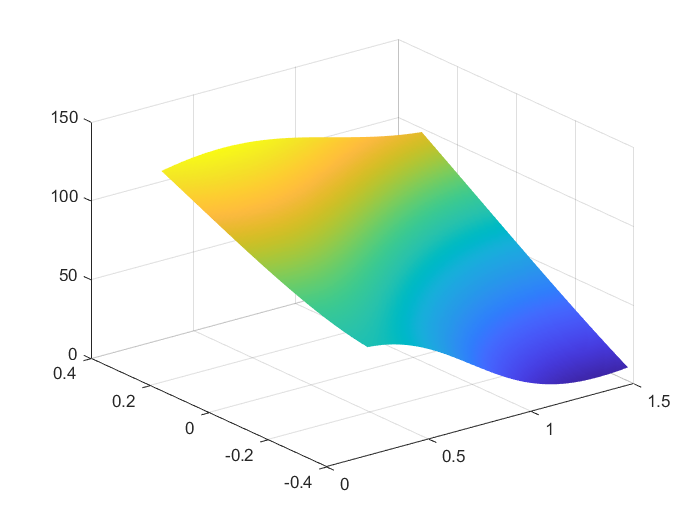

zsurf =   Surface with properties:

       EdgeColor: [0 0 0]
       LineStyle: 'none'
       FaceColor: 'flat'
    FaceLighting: 'flat'
       FaceAlpha: 1
           XData: [201×201 double]
           YData: [201×201 double]
           ZData: [201×201 double]
           CData: [201×201 double]

  Show all properties


zsurf = surf(phiX,phiZ,C_z,'LineStyle','none')

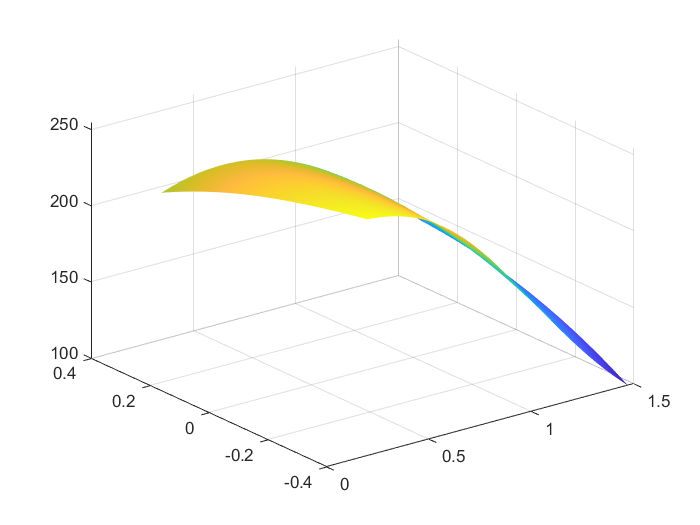

xsurf =   Surface with properties:

       EdgeColor: [0 0 0]
       LineStyle: 'none'
       FaceColor: 'flat'
    FaceLighting: 'flat'
       FaceAlpha: 1
           XData: [201×201 double]
           YData: [201×201 double]
           ZData: [201×201 double]
           CData: [201×201 double]

  Show all properties


xsurf = surf(phiX,phiZ,C_r,'LineStyle','none')

## Function fitting 

The figures above are surfaces (height or radial distance)  which are dependant on the motor positions. As these surfaces are continuous it is possible to do a function fit such that we get a simple equation describing the position. For this we can use the curve fitting tool, which can be openend using the following command

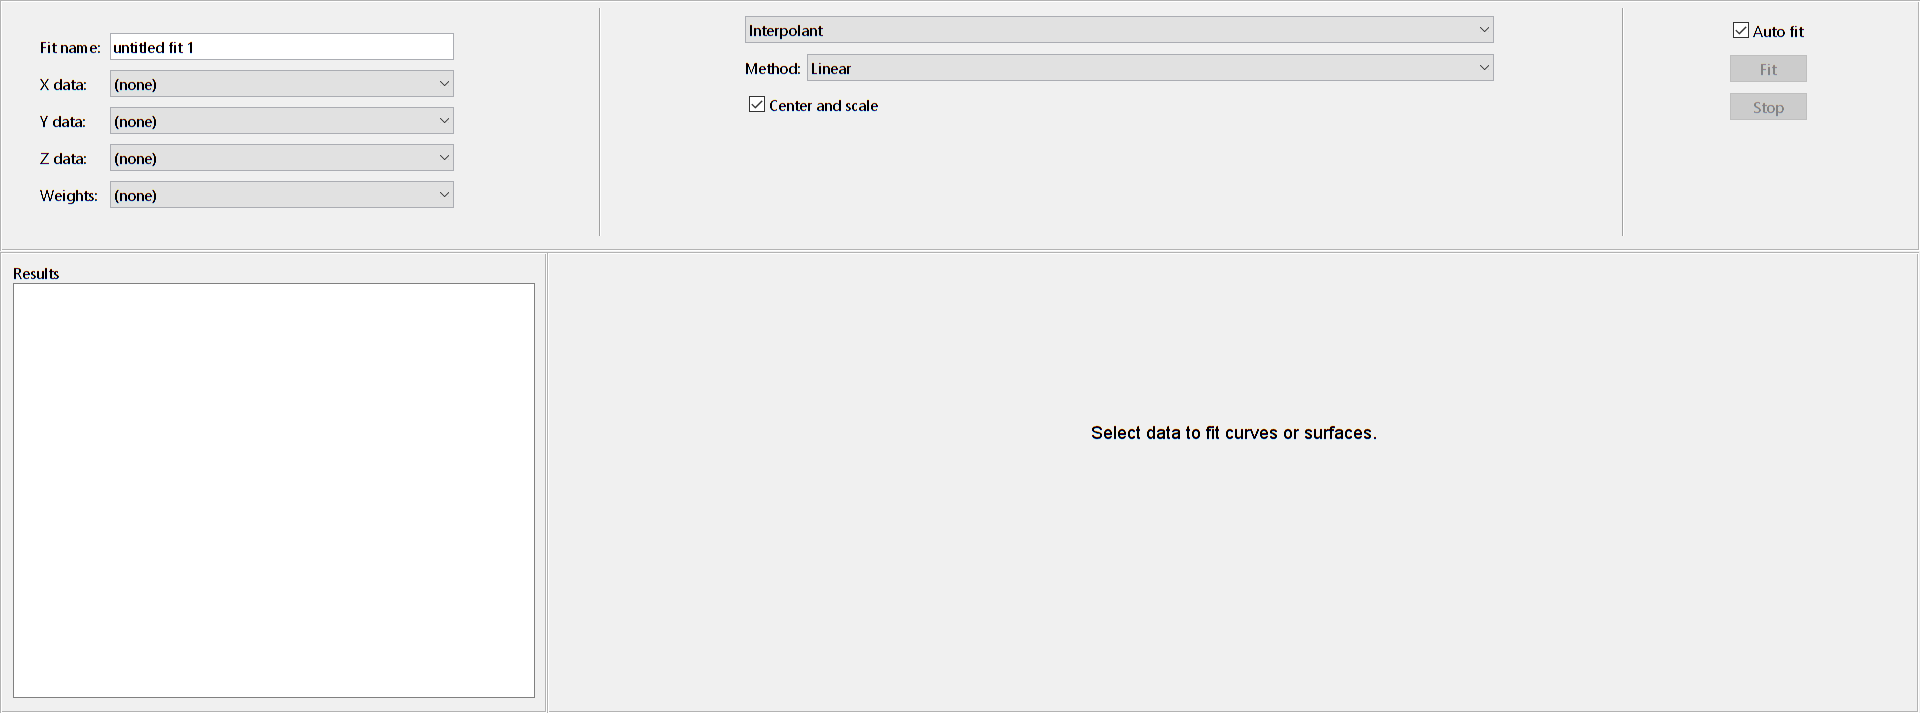

cftool

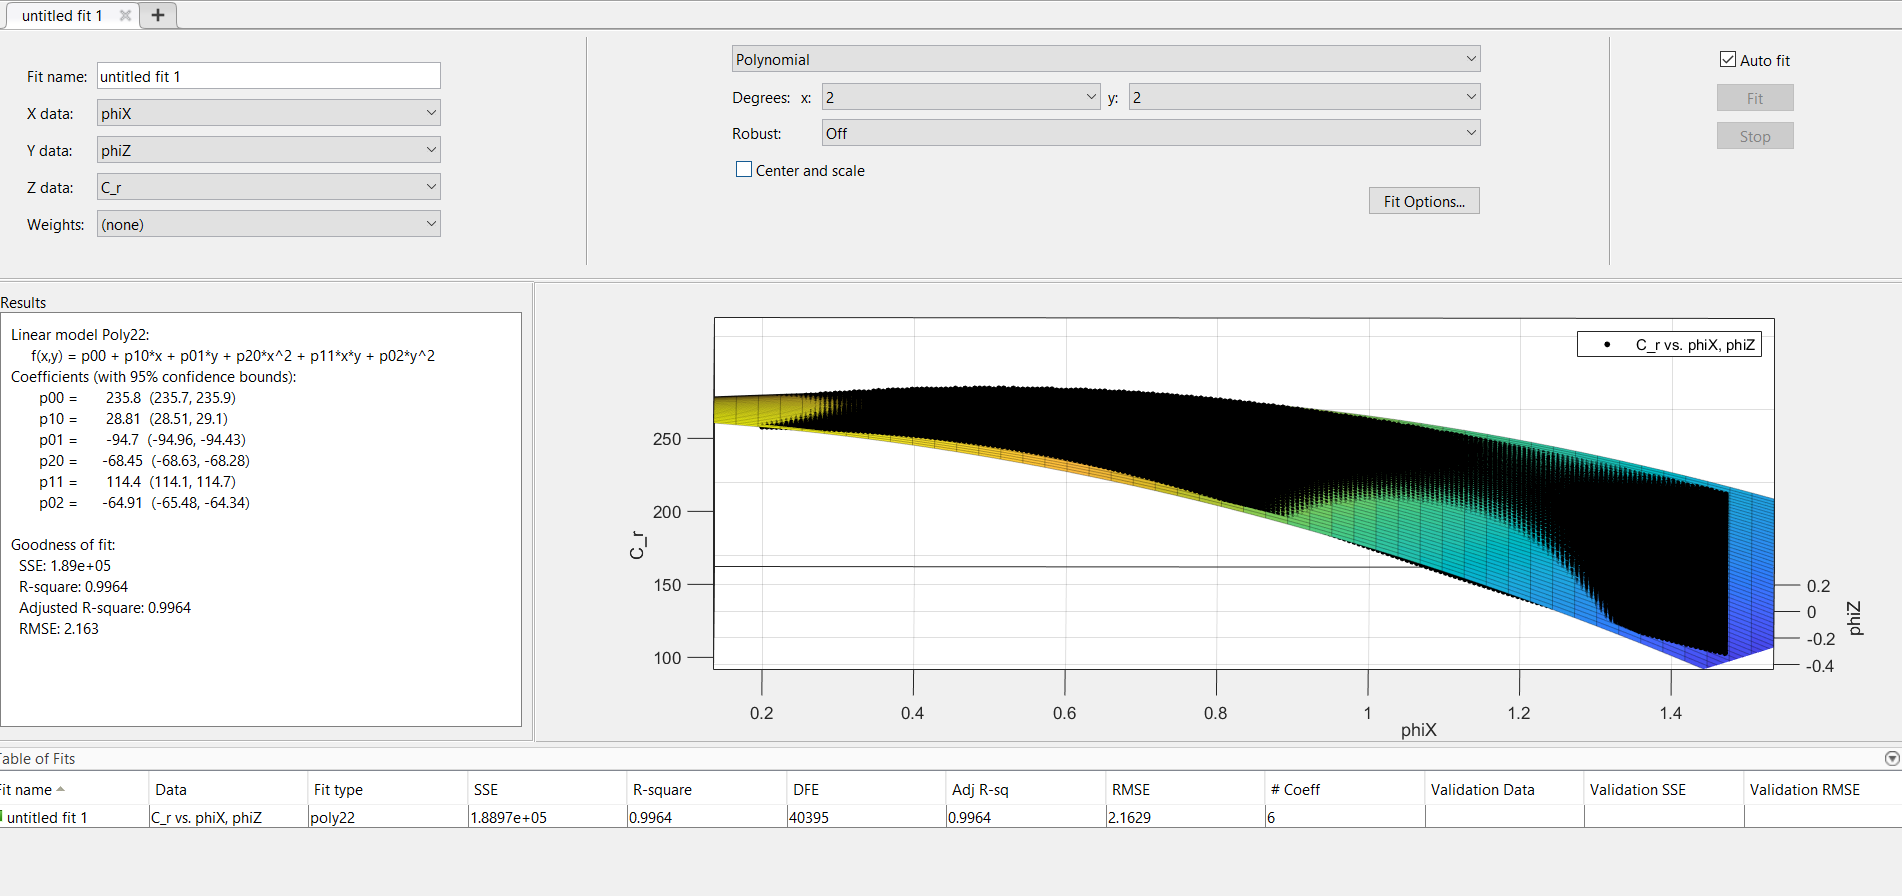

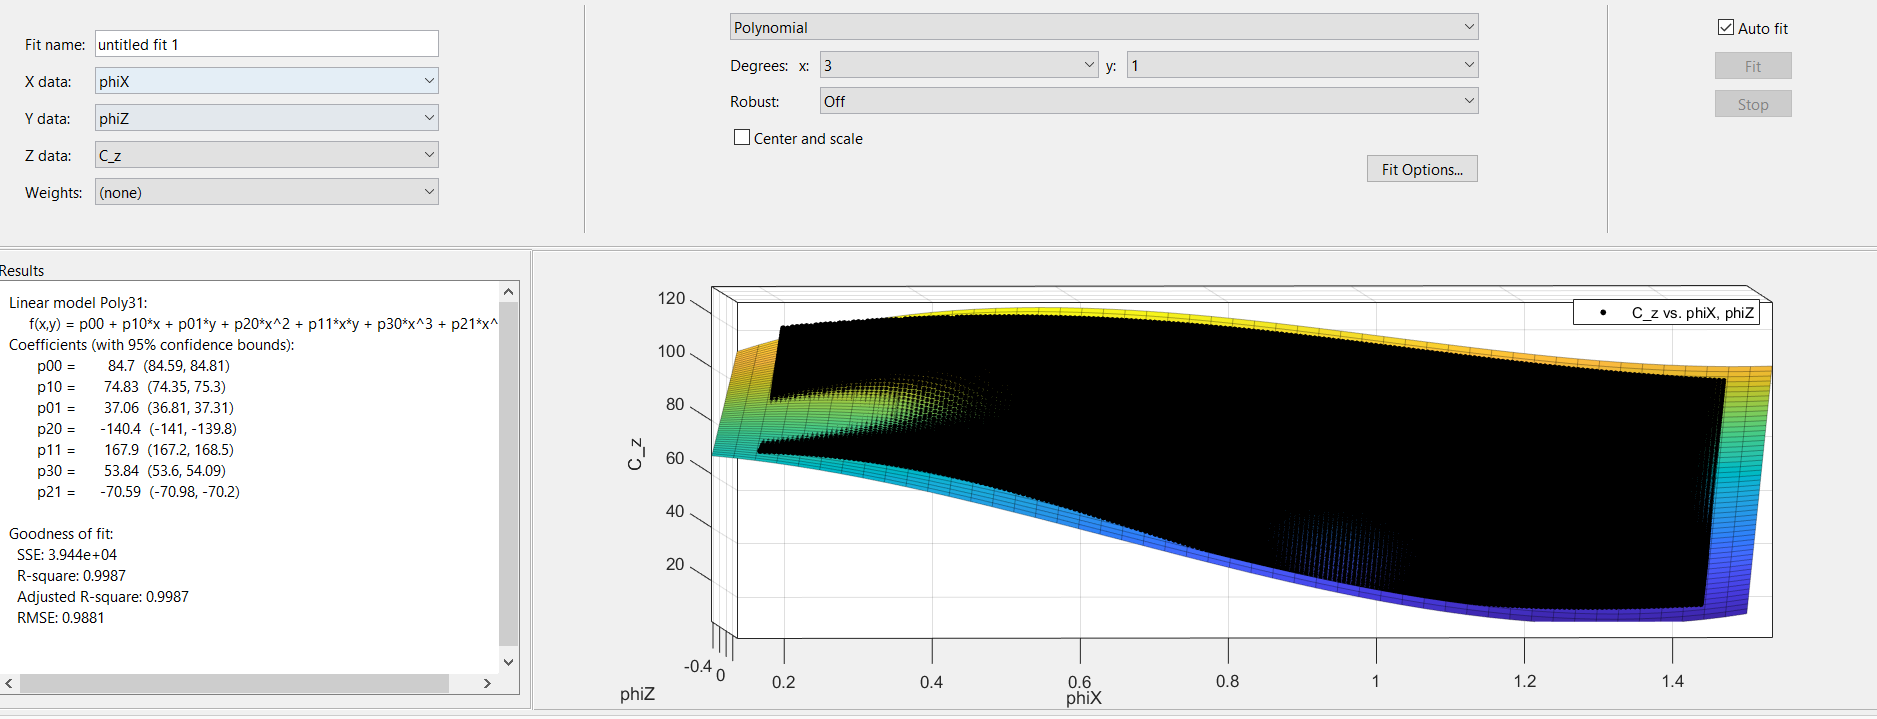

In the figures above the surfaces have been fitted with a polynomial function which both have a very high R squared value, meaning that they accurately describe the surface.

Using these functions it is easy to take the derivative w.r.t. a motor and get the velocity of the end effector from the velocity of the motor. With this we can choose to have as  complicated (and accurate) or as simplified equations for the position of the arm which then can be used to compute forces related to the damping and inertia and springs